% image
imageFolder = 'imagethree/cu_0.025/';
imageFiles = dir(fullfile(imageFolder, '*.png')); % フォーマットに応じて変更
imgcnt = 2;
imagePath = fullfile(imageFolder, imageFiles(imgcnt).name);
%color space
cform1 = makecform('xyz2xyl')

cform1 = フィールドをもつ struct :
            c_func: @xyz2xyl
     ColorSpace_in: 'xyz'
    ColorSpace_out: 'xyl'
          encoding: 'double'
             cdata: [1×1 struct]


cform2 = makecform('xyl2xyz')

cform2 = フィールドをもつ struct :
            c_func: @xyl2xyz
     ColorSpace_in: 'xyl'
    ColorSpace_out: 'xyz'
          encoding: 'double'
             cdata: [1×1 struct]


%callibration
callibration_Path = 'callibration/'

callibration_Path = 'callibration/'

spectrum_data = readmatrix(fullfile(callibration_Path,'spectr.csv'));
c = tnt.RgbConverter(spectrum_data);
gamma_converter =load(fullfile(callibration_Path,"gamma_converter.mat")).gamma_converter;

%---input sRGB already tonemapped---

originalImg = double(imread(imagePath));
srgbImgin = cat(3,originalImg(:,:,1)/255,originalImg(:,:,2)/255,originalImg(:,:,3)/255);
xyzImgin = rgb2xyz(srgbImgin);
xyYImgin = applycform(xyzImgin,cform1);
LDR_Y = xyYImgin(:,:,3)*100;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform2);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);


%}
%---input sRGB already tonemapped---
%---input sRGB don't tonemapped---
%{
originalImg = double(imread(imagePath));
srgbImgin = cat(3,originalImg(:,:,1)/255,originalImg(:,:,2)/255,originalImg(:,:,3)/255);
xyzImgin = rgb2xyz(srgbImgin);
xyYImgin = applycform(xyzImgin,cform1);
xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
%LDR_Y = xyYImgin(:,:,3)*100;
%LDR_Y = ReinhardTMO(xyYImgin(:,:,3))*100;
%LDR_Y = ReinhardTMO(xyYImgin(:,:,3),1,1,'global',8,1.19)*100;
LDR_Y = Reinhard(xyYImgin(:,:,3),1)*100;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform2);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---input sRGB don't tonemapped---
% confirm
elements_above_one = digital_rgb(digital_rgb >= 1);
disp(elements_above_one);

     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1

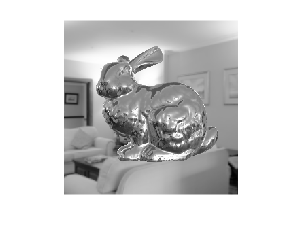

imshow(srgbImgin);

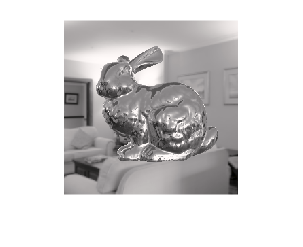

imshow(digital_rgb);